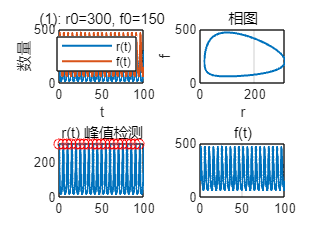

%% Lotka–Volterra 捕食模型数值实验

clear; close all; clc;

alpha = 0.01;

%% ========= (1) r0=300, f0=150 ==========
r0 = 300; f0 = 150; tmax = 100;
[t1,y1,T1] = solve_and_plot(r0,f0,alpha,tmax,1,'(1)');

fprintf('(1) 估算周期 T = %.6f\n',T1);

(1) 估算周期 T = 5.000315


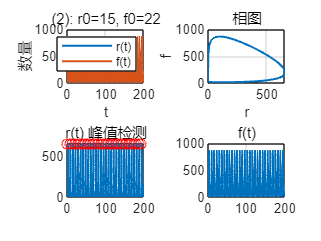


%% ========= (2) r0=15, f0=22 =============
r0 = 15; f0 = 22; tmax = 200;
[t2,y2,T2] = solve_and_plot(r0,f0,alpha,tmax,2,'(2)');

fprintf('(2) 估算周期 T = %.6f\n',T2);

(2) 估算周期 T = 6.623847


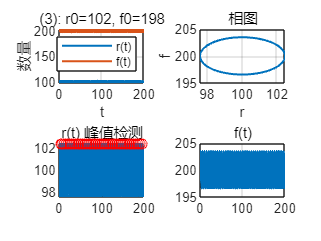


%% ========= (3) r0=102, f0=198 ===========
r0 = 102; f0 = 198; tmax = 200;
[t3,y3,T3] = solve_and_plot(r0,f0,alpha,tmax,3,'(3)');

fprintf('(3) 估算周期 T = %.6f\n',T3);

(3) 估算周期 T = 4.443468


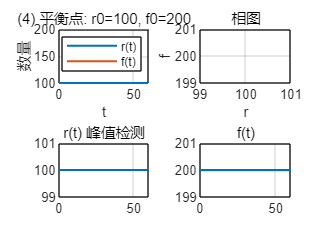


%% ========= (4) 平衡点 ===========
r_eq = 1/alpha;
f_eq = 2/alpha;

r0 = r_eq; f0 = f_eq; tmax = 60;
[t4,y4,T4] = solve_and_plot(r0,f0,alpha,tmax,4,'(4) 平衡点');

fprintf('(4) 在平衡点附近数值解应几乎不变。\n');

(4) 在平衡点附近数值解应几乎不变。



% 线性化理论周期
J = [0 -1; 2 0];
omega = abs(imag(eig(J(1))));
T_lin = 2*pi/omega;
fprintf('线性化理论周期 T_lin = %.6f\n',T_lin);

线性化理论周期 T_lin = Inf


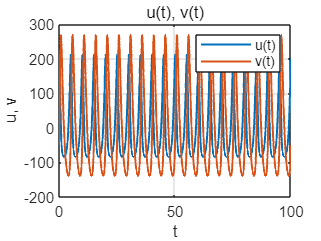


%% u(t)=r-1/α, v(t)=f-2/α 示例图（用第1组）
figure(5); clf;
u = y1(:,1)-r_eq;
v = y1(:,2)-f_eq;
plot(t1,u,'LineWidth',1.2); hold on;
plot(t1,v,'LineWidth',1.2);
xlabel('t'); ylabel('u, v');
legend('u(t)','v(t)');
title('u(t), v(t)');
grid on;


%% ============================================================
%                     以下为局部函数（必须放在文末）
%% ============================================================

clear; clc; close all;

%% 1. 参数设置 (原子单位制: hbar=1, m=1)
L_total = 10;      % 计算区域总宽度 [-5, 5]
N = 1000;          % 离散点数
x = linspace(-L_total/2, L_total/2, N)';
dx = x(2) - x(1);

% 势阱参数
a = 1;             % 势阱半宽 (阱宽 2a)
V0 = 20;           % 势阱深度
V = zeros(N, 1);
V(abs(x) > a) = V0; % 势阱外部为 V0，内部为 0

%% 2. 数值解：有限差分法构建哈密顿量矩阵
% 动能矩阵 T = -0.5 * d^2/dx^2
e = ones(N, 1);
L_op = spdiags([e -2*e e], -1:1, N, N); % 二阶导数算子
T = -0.5 * L_op / (dx^2);

% 势能矩阵 V (对角阵)
V_mat = spdiags(V, 0, N, N);

% 总哈密顿量
H = T + V_mat;

% 求解特征值和特征向量
% 只求小于 V0 的束缚态能级
[psi, E_diag] = eigs(H, 10, 'sm'); % 'sm' 寻找最小模的特征值
E_num = diag(E_diag);
E_num = sort(E_num(E_num < V0));   % 筛选束缚态并排序

%% 3. 解析解：求解超越方程
% k = sqrt(2E), k0 = sqrt(2V0)
% 偶宇称: k*tan(k*a) = sqrt(k0^2 - k^2)
% 奇宇称: -k*cot(k*a) = sqrt(k0^2 - k^2)

E_ana = [];
fun_even = @(E) sqrt(2*E).*tan(sqrt(2*E)*a) - sqrt(2*V0 - 2*E);
fun_odd  = @(E) -sqrt(2*E).*cot(sqrt(2*E)*a) - sqrt(2*V0 - 2*E);

% 粗略扫描寻找初值
E_scan = linspace(0.1, V0-0.1, 100);
for i = 1:length(E_scan)-1
    % 寻找偶宇称解
    if fun_even(E_scan(i)) * fun_even(E_scan(i+1)) < 0
        root = fzero(fun_even, [E_scan(i), E_scan(i+1)]);
        E_ana = [E_ana; root];
    end
    % 寻找奇宇称解
    if fun_odd(E_scan(i)) * fun_odd(E_scan(i+1)) < 0
        root = fzero(fun_odd, [E_scan(i), E_scan(i+1)]);
        E_ana = [E_ana; root];
    end
end
E_ana = sort(E_ana);

%% 4. 结果对比输出
fprintf('--- 有限深方势阱能级对比 (V0=%.1f, a=%.1f) ---\n', V0, a);

--- 有限深方势阱能级对比 (V0=20.0, a=1.0) ---


fprintf('%-10s %-15s %-15s %-15s\n', '能级序号', '数值解 (E_num)', '解析解 (E_ana)', '相对误差(%)');

能级序号       数值解 (E_num)     解析解 (E_ana)     相对误差(%)        



len = min(length(E_num), length(E_ana));
for i = 1:len
    err = abs(E_num(i) - E_ana(i)) / E_ana(i) * 100;
    fprintf('%-10d %-15.6f %-15.6f %-15.2e\n', i, E_num(i), E_ana(i), err);
end

1          0.916157        0.917870        1.87e-01       
2          3.639364        1.233701        1.95e+02       
3          8.076997        3.646201        1.22e+02       
4          13.976952       4.934802        1.83e+02       
5          19.983492       8.092151        1.47e+02       


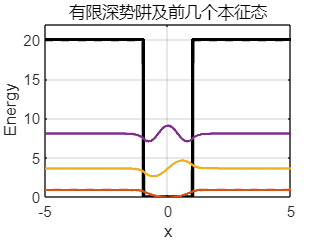


%% 5. 绘图 (可选)
figure;
plot(x, V, 'k-', 'LineWidth', 2); hold on;
% 绘制前3个波函数示意图(加上能级高度)
scale = 1; 
for i = 1:min(3, len)
    plot(x, psi(:,i)/max(abs(psi(:,i)))*scale + E_num(i), 'LineWidth', 1.5);
end
title('有限深势阱及前几个本征态');
xlabel('x'); ylabel('Energy');
ylim([0, V0+2]);
grid on;

%% --- 主程序开始 ---
clear; clc; close all;

% 1. 定义计算区间
L = 6; % 无穷远边界近似 [-6, 6]
xmesh = linspace(-L, L, 50); % 初始网格

fprintf('--- 利用 bvp4c 计算谐振子最低 2 个能级 ---\n');

--- 利用 bvp4c 计算谐振子最低 2 个能级 ---


fprintf('方程: -y'''' + x^2*y = E*y  =>  理论能级 E_n = 2n + 1\n\n');

方程: -y'' + x^2*y = E*y  =>  理论能级 E_n = 2n + 1




%% --- 计算基态 (n=0) ---
% 猜测 E ≈ 1, 波函数形状为高斯分布 exp(-x^2/2)
guess_E0 = 1.0;
solinit0 = bvpinit(xmesh, @guess_func_0, guess_E0);

% 调用求解器 bvp4c
% 注意：这里直接传入函数句柄 @ode_fun 和 @bc_fun
sol0 = bvp4c(@ode_fun, @bc_fun, solinit0);

E0 = sol0.parameters; % 提取计算得到的本征值
fprintf('基态 (n=0):\n');

基态 (n=0):


fprintf('  计算能级 E = %.6f\n', E0);

  计算能级 E = 1.000015


fprintf('  理论能级 E = 1.000000\n\n');

  理论能级 E = 1.000000




%% --- 计算第一激发态 (n=1) ---
% 猜测 E ≈ 3, 波函数形状为奇函数 x*exp(-x^2/2)
guess_E1 = 3.0;
solinit1 = bvpinit(xmesh, @guess_func_1, guess_E1);

% 调用求解器 bvp4c
sol1 = bvp4c(@ode_fun, @bc_fun, solinit1);

E1 = sol1.parameters;
fprintf('第一激发态 (n=1):\n');

第一激发态 (n=1):


fprintf('  计算能级 E = %.6f\n', E1);

  计算能级 E = 3.000043


fprintf('  理论能级 E = 3.000000\n');

  理论能级 E = 3.000000


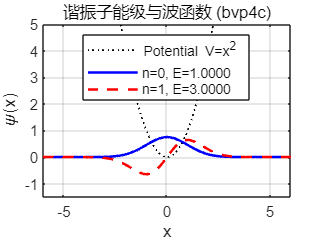


%% --- 绘图 ---
figure;
% 绘制势能 V = x^2 (为了参考)
x_plot = linspace(-L, L, 200);
plot(x_plot, x_plot.^2, 'k:', 'LineWidth', 1.0, 'DisplayName', 'Potential V=x^2'); 
hold on;

% 绘制基态波函数
% sol0.y(1,:) 是波函数 psi
plot(sol0.x, sol0.y(1,:), 'b-', 'LineWidth', 1.5, 'DisplayName', ['n=0, E=' num2str(E0, '%.4f')]);

% 绘制第一激发态波函数
plot(sol1.x, sol1.y(1,:), 'r--', 'LineWidth', 1.5, 'DisplayName', ['n=1, E=' num2str(E1, '%.4f')]);

title('谐振子能级与波函数 (bvp4c)');
xlabel('x'); ylabel('\psi(x)');
ylim([-1.5, 5]); % 调整Y轴范围以便看到势能和波函数
legend('Location', 'best');
grid on;


%% --- 辅助函数定义区 (放在脚本最后) ---

% 1. 微分方程定义
% y(1) = psi
% y(2) = psi'
% y(3) = int(psi^2) 用于归一化
% p    = 本征值 E (未知参数)

function dydx = ode_fun(x, y, p)
    E = p; 
    % 此时方程为: psi'' - (x^2 - E)psi = 0
    dydx = [ y(2);               % y(1)'
             (x^2 - E) * y(1);   % y(2)'
             y(1)^2 ];           % y(3)' = psi^2
end

% 2. 边界条件定义
% ya 是左边界 [-L] 的值, yb 是右边界 [L] 的值
function res = bc_fun(ya, yb, p)
    res = [ ya(1);       % 左边界 psi(-L) = 0
            yb(1);       % 右边界 psi(L)  = 0
            ya(3);       % 积分初始值 int(-L) = 0
            yb(3) - 1 ]; % 积分结束值 int(L)  = 1 (归一化条件)
end

% 3. 基态初始猜测函数 (偶函数)
function v = guess_func_0(x)
    v = [ exp(-x^2/2);     % psi 猜测
          -x*exp(-x^2/2);  % psi' 猜测
          0 ];             % 积分项猜测 (初始设为0即可)
end

% 4. 第一激发态初始猜测函数 (奇函数)
function v = guess_func_1(x)
    v = [ x*exp(-x^2/2);           % psi 猜测
          (1-x^2)*exp(-x^2/2);     % psi' 猜测
          0 ];
end
function dydt = LV_ode(~,y,alpha)
    r = y(1); 
    f = y(2);
    dr = 2*r - alpha*r*f;
    df = -f + alpha*r*f;
    dydt = [dr; df];
end

function [t,y,T] = solve_and_plot(r0,f0,alpha,tmax,fig_id,title_tag)
    opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
    [t,y] = ode45(@(tt,yy) LV_ode(tt,yy,alpha), [0 tmax], [r0;f0], opts);
    r = y(:,1); f = y(:,2);

    figure(fig_id); clf;

    % r(t),f(t)
    subplot(2,2,1);
    plot(t,r,'LineWidth',1.2); hold on;
    plot(t,f,'LineWidth',1.2);
    legend('r(t)','f(t)'); xlabel('t'); ylabel('数量');
    title(sprintf('%s: r0=%g, f0=%g',title_tag,r0,f0));
    grid on;

    % 相图
    subplot(2,2,2);
    plot(r,f,'LineWidth',1.2);
    xlabel('r'); ylabel('f'); grid on; title('相图');

    % 用r(t)找周期
    [pks,locs] = findpeaks(r,t,'MinPeakProminence',max(r)*0.02);

    if length(locs)>2
        T = mean(diff(locs));
    else
        T = NaN;
    end

    subplot(2,2,3);
    plot(t,r,'LineWidth',1.2); hold on;
    plot(locs,pks,'ro');
    title('r(t) 峰值检测'); grid on;

    subplot(2,2,4);
    plot(t,f,'LineWidth',1.2); 
    title('f(t)'); grid on;
end